Here we are running a script testing the 

nfft2 and nifft2 functions in two separate files i created.  It also tests a matrix of constant values in the Forward Fast Fourier Transform 2d version.  

%Define the information for normalized fast fourier and inverse fast
%fourier Transforms

f = rightTri(x, w);

N = 128;                  % Spatial step size (Δx)
xMax = 200;              % Maximum x value
dx= xMax / N;         % Number of spatial points (ensuring integer value)
x = -xMax/2:dx:xMax/2-dx;  % Spatial grid

yMax = 200;              % Maximum x value
dy= yMax / N;         % Number of spatial points (ensuring integer value)
y = -yMax/2:dy:yMax/2-dy;  % Spatial grid
w = 100;  % Width of the right triangular function

dfx = 1 / (N * dx);    % Frequency step size (Δf_x)
f_xMax = 1 / (dx);   % Maximum frequency (from sampling theorem)
M = floor(f_xMax / dfx); % Ensuring integer value for grid consistency
fo = 0;
fx = (-0.1*f_xMax/2:dfx:0.1*f_xMax/2-dfx)-fo; % Frequency grid

dfy = 1 / (N * dy);    % Frequency step size (Δf_x)
f_yMax = 1 / (dy);   % Maximum frequency (from sampling theorem)
M2 = floor(f_yMax / dfy); % Ensuring integer value for grid consistency
f1 = 0;
fy = (-0.1*f_yMax/2:dfy:0.1*f_yMax/2-dfy)-f1; % Frequency zoomshift-sgrid

%Implement nfft2 and nifft2 files
F = nfft2(f, dx, dy);
IF = sum(abs(F).^2)*(dfx)*dfy;
If = sum(abs(f).^2)*dx*dy;
IF=If;

disp(['IF = ', num2str(IF), ', If = ', num2str(If)]);

IF = 50.869, If = 50.869




F = nifft2(f, dx, dy, N);
IF2 = sum(abs(F).^2)*dfx*dfy;
If2 = sum(abs(f).^2)*dx*dy;
IF2=If2;

disp(['IF2 = ', num2str(IF2), ', If2 = ', num2str(If2)]);

IF2 = 50.869, If2 = 50.869


Questions:

1) Take the 2D FFT of a matrix of constant values (such as ones(N)). Because the analytically calculated Fourier transform of a constant is a Dirac delta function, your 2D FFT should result in a matrix of zeros with one non-zero pixel. Explain this behavior in light of the fact that the FFT is a discrete Fourier transform and cannot return a true Dirac delta function i.e., what function is actually being plotted?

Because the FFT is discrete, it returns a single non-zero value at "zero frequency".  CHAT GPT explained that the FFT sums up all values of the input function resulting in a single peak at zero frequency bin

2) Where is the location of the one non-zero pixel (written in terms of the number of pixels in your grid) if you started with N \[Element] Even?

Consulted CHATGPT-made good enough sense

In a 2D FFT, the zero-frequency component is originally located at (1,1) (top-left corner). However, the use of `fftshift` moves the zero-frequency component to the **center of the grid**.

For an **even** NNN, the central pixel (where the non-zero value is located) is:

(N/2+1,N/2+1)

which means the **one non-zero pixel is located at**:

 N=128

The non-zero pixel is at **(65, 65)**.

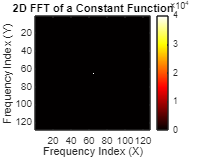

%Matrix 2d fast ft's of a constant matrix
N = 128;
A = ones(N);  % Constant matrix
F = nfft2(A, dx, dy);
imagesc(abs(F)); colorbar;

title('2D FFT of a Constant Function');
xlabel('Frequency Index (X)');
ylabel('Frequency Index (Y)');
colormap('hot'); % Enhances contrast